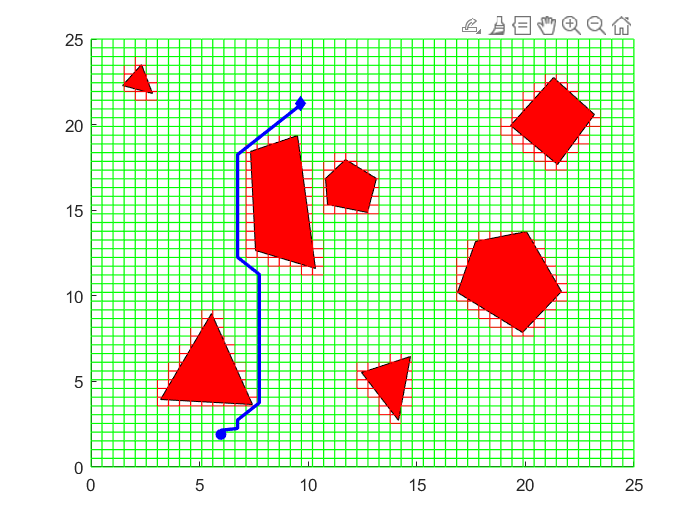

clear;
load('obstacles.mat');
% Parametry
ROOM_WIDTH = 25;
ROOM_LENGTH = 25;
RESOLUTION = 0.5;

% Przeszkody
%obstacles = get_obstacles(ROOM_WIDTH, ROOM_HEIGHT);
%save('obstacles.mat','obstacles');

% Siatka zajętości
warning('off','all');
grid = get_occupancy(ROOM_WIDTH, ROOM_LENGTH, RESOLUTION, obstacles);


% Ścieżka - algorytm Astar
start_pos = ginput(1);
goal_pos = ginput(1);

path = get_astar_path(ROOM_WIDTH, ROOM_LENGTH, start_pos, goal_pos, RESOLUTION, grid);
plot(path(:,2), path(:,1), 'b-', "LineWidth", 2);
plot(start_pos(1) + RESOLUTION / 2, start_pos(2) + RESOLUTION / 2, 'bo', "MarkerFaceColor", 'b');
plot(goal_pos(1) + RESOLUTION / 2, goal_pos(2), 'bd', "MarkerFaceColor", 'b');
hold off;

function path = get_astar_path(room_width, room_length, start_pose, goal_pose, resolution, occupancy_grid)
    if start_pose(1) <= 0
        start_pose(1) = 0.001;
    end
    if start_pose(2) <= 0
        start_pose(2) = 0.001;
    end
    if goal_pose(1) <= 0
        goal_pose(1) = 0.001;
    end
    if goal_pose(2) <= 0
        goal_pose(2) = 0.001;
    end

    % Inicjalizacja parametrów algorytmu
    num_nodes = ceil(room_width / resolution) * ceil(room_length / resolution);
    G = Inf(num_nodes, 1); % Koszt dojścia do węzła
    H = zeros(num_nodes, 1); % Przybliżony koszt od węzła do celu
    F = Inf(num_nodes, 1); % Całkowity koszt (G + H)
    parent = zeros(num_nodes, 1); % Indeks poprzedniego węzła w ścieżce

    % Konwersja współrzędnych na indeks węzła
    coord_to_index = @(x, y) ceil(y / resolution) + ceil(x / resolution) * ceil(room_length / resolution);

    % Konwersja indeksu węzła na współrzędne
    index_to_coord = @(idx) [(mod(idx - 1, ceil(room_length / resolution)) * resolution)...
                             (floor((idx - 1) / ceil(room_length / resolution)) * resolution)];

    % Początkowy węzeł
    start_node = coord_to_index(start_pose(1), start_pose(2));
    G(start_node) = 0;
    H(start_node) = norm(start_pose - goal_pose);
    F(start_node) = H(start_node);

    % Główna pętla algorytmu A*
    while true
        % Znajdowanie węzła o najmniejszym koszcie F
        [~, current] = min(F);
        if current == coord_to_index(goal_pose(1), goal_pose(2))
            break; % Cel osiągnięty
        end

        % Aktualizacja kosztów sąsiednich węzłów
        neighbors = get_neighbors(current, room_length, resolution, num_nodes);
        for i = 1:length(neighbors)
            neighbor = neighbors(i);
            if occupancy_grid(neighbor) == 1 % Sprawdzenie zajętości
                continue;
            end
            tentative_G = G(current) + norm(index_to_coord(current) - index_to_coord(neighbor));
            if tentative_G < G(neighbor)
                parent(neighbor) = current;
                G(neighbor) = tentative_G;
                H(neighbor) = norm(index_to_coord(neighbor) - goal_pose);
                F(neighbor) = G(neighbor) + H(neighbor);
            end
        end

        % Oznaczenie bieżącego węzła jako odwiedzony
        F(current) = Inf;
    end

    % Odtworzenie ścieżki
    path = [];
    current = coord_to_index(goal_pose(1), goal_pose(2));
    while current ~= start_node
        path = [index_to_coord(current); path];
        current = parent(current);
    end
    path = [[start_pose(2) start_pose(1)]; path] + resolution / 2;
end

function neighbors = get_neighbors(current, room_length, resolution, num_nodes)
    % Pobranie sąsiadów dla danego węzła
    neighbors = [current - 1, current + 1, current - ceil(room_length / resolution), current + ceil(room_length / resolution),...
                 current - ceil(room_length / resolution) - 1, current - ceil(room_length / resolution) + 1,...
                 current + ceil(room_length / resolution) - 1, current + ceil(room_length / resolution) + 1];
    neighbors(neighbors <= 0 | neighbors > num_nodes) = []; % Usunięcie węzłów poza granicami siatki
end

% function path = get_Astar_path(room_length, start_pos, goal_pos, occupancy_grid, resolution)
%     % Utwórz listę otwartą, która będzie przechowywać komórki do odwiedzenia
%     to_visit_cells = [[start_pos(1) / resolution, (room_length - start_pos(2)) / resolution], 0, 0]; % Format: [x, y, f, parent_index]
%     % Utwórz listę zamkniętą, która będzie przechowywać już odwiedzone komórki
%     already_visited_cells = [];
%     goal_pos = [goal_pos(1) / resolution, (room_length - goal_pos(2)) / resolution];
% 
%     % Pobierz rozmiar siatki zajętości
%     border_coordinates = size(occupancy_grid);
% 
%     % Główna pętla algorytmu A*
%     while ~isempty(to_visit_cells)
%         % Wybierz komórkę z najniższym kosztem f
%         [~, index] = min(to_visit_cells(:, 3));
%         current_cell = to_visit_cells(index, :);
% 
%         % Jeżeli wybrana komórka jest komórką końcową, zakończ algorytm
%         if isequal(current_cell(1:2), goal_pos)
% 
%             path = reconstructPath(already_visited_cells, current_cell);
%             %path = path*n; 
%             real_grid = zeros(50);
%             for i = 1 : size(path, 1)
%                 actual_cor = path(i, 1:2);
%                 real_grid(actual_cor(1), actual_cor(2)) = 2;
%             end
%             path = real_grid;
%             return;
%         end
% 
%         % Usuń wybraną komórkę z listy otwartej i dodaj ją do listy zamkniętej
%         to_visit_cells(index, :) = [];
%         already_visited_cells = [already_visited_cells; current_cell];
% 
%         % Wygeneruj sąsiadów wybranej komórki
%         neighbors = generateNeighbors(current_cell(1:2), border_coordinates, occupancy_grid);
% 
%         % Iteruj przez sąsiadów
%         for i = 1:size(neighbors, 1)
%             neighbor = neighbors(i, :);
% 
%             % Sprawdź, czy sąsiad ma wartość 0 w occ_grid
%             if occupancy_grid(neighbor(1), neighbor(2)) == 1
%                 continue; % Pomiń sąsiada, jeśli jest to przeszkoda
%             end
% 
%             % Oblicz wartość f dla sąsiada
%             g = current_cell(3) + 1; % Koszt dotarcia do sąsiada z punktu startowego
%             h = norm(neighbor - goal_pos); % Odległość euklidesowa do punktu końcowego
%             f = g + h; % Całkowity koszt
% 
% 
%             % Jeśli sąsiad nie znajduje się na liście otwartej, dodaj go
%             if ~any(ismember(neighbor, to_visit_cells(:, 1:2), 'rows'))
%                 to_visit_cells = [to_visit_cells; neighbor, f, size(already_visited_cells, 1)]; % Dodaj indeks rodzica
%             else
%                 % Jeśli sąsiad znajduje się na liście otwartej, zaktualizuj wartość f jeżeli nowa droga jest krótsza
%                 index = find(ismember(to_visit_cells(:, 1:2), neighbor, 'rows'));
%                 if f < to_visit_cells(index, 3)
%                     to_visit_cells(index, 3) = f;
%                     % Zaktualizuj indeks rodzica
%                     to_visit_cells(index, 4) = size(already_visited_cells, 1);
%                 end
%             end
%         end
%     end
% 
%     % Jeśli lista otwarta jest pusta, a cel nie został osiągnięty, zwróć pustą ścieżkę
%     path = [];
%     disp('Nie można odnaleźć ścieżki.');
% end
% 
% function path = reconstructPath(already_visited_cells, end_cell)
%     % Inicjalizacja ścieżki
%     path = [];
%     % Ustaw bieżącą komórkę na końcową komórkę
%     current_cell = end_cell;
% 
%     % Buduj ścieżkę od końca do początku
%     while current_cell(4) ~= 0 % Dopóki istnieje komórka rodzica
%         % Dodaj bieżącą komórkę do ścieżki
%         path = [current_cell(1:2); path];
%         % Znajdź komórkę rodzica na podstawie indeksu
%         current_cell = already_visited_cells(current_cell(4), :);
%     end
%     % Dodaj komórkę początkową do ścieżki
%     path = [current_cell(1:2); path];
% end
% 
% function neighbors = generateNeighbors(cell_coordinates, border_coordinates ,occ_grid)
%     % Generuj sąsiadów dla danej komórki
%     x = cell_coordinates(1);
%     y = cell_coordinates(2);
% 
%     % Możliwe przesunięcia względem bieżącej komórki
%     %shifts = [-1, 0; 1, 0; 0, -1; 0, 1; 1 1; -1 -1; 1 -1; -1 1];
%     shifts = [-1, 0; 1, 0; 0, -1; 0, 1];
%     neighbors = [];
%     for i = 1:size(shifts, 1)
%         neighbor_x = x + shifts(i, 1);
%         neighbor_y = y + shifts(i, 2);
% 
%         % Sprawdź, czy sąsiad mieści się w granicach siatki
%         if neighbor_x >= 1 && neighbor_x <= border_coordinates(1) && neighbor_y >= 1 && neighbor_y <= border_coordinates(2) 
%             if (occ_grid(neighbor_x, neighbor_y) == 0)
%                 neighbors = [neighbors; neighbor_x, neighbor_y];
%             end
%         end
%     end
% end

function obstacles = get_obstacles(room_x, room_y)
    figure; hold on;
    axis([0 room_x 0 room_y]);
    grid on;
    no_obst = inputdlg("Podaj liczbę przeszkód");
    no_obst = str2double(no_obst{1});
    obstacles = {};
    i = 0;
    while i < no_obst
        n = inputdlg("Podaj liczbę kątów przeszkody");
        n = str2double(n{1});
        while n < 3
            n = inputdlg("Podaj liczbę kątów przeszkody");
            n = str2double(n{1});
        end

        new_obstacle = [];
        [x, y] = ginput(1);
        new_obstacle = [new_obstacle; x, y];
        plot(x, y, "r*");
        j = 0;
        while j < n - 1
            try
                [x, y] = ginput(1);  
            catch
                break;
            end
        
            if (~isempty(x)) & (~isempty(y))
                new_obstacle = [new_obstacle; x, y];
                plot(x, y, "r*");
                line([new_obstacle(end - 1, 1), new_obstacle(end, 1)], [new_obstacle(end - 1, 2), new_obstacle(end, 2)], "Color", "r")
            end
            j = j + 1;
        end

        obstacles = [obstacles new_obstacle];

        i = i + 1;
    end
    
    hold off;
end

function occupancy_grid = get_occupancy(room_width, room_height, resolution, obstacles)
    no_rect_h = ceil(room_height / resolution);
    no_rect_w = ceil(room_width / resolution);
    
    grid_matrix_2d = zeros(no_rect_h, no_rect_w, 2);
    
    for i = 1 : no_rect_h
        grid_matrix_2d(i, :, 1) = linspace(0, room_width, no_rect_w);
    end
    
    for i = 1 : no_rect_w
        grid_matrix_2d(:, i, 2) = linspace(0, room_height, no_rect_h);
    end
    
    % Przeszkody
    figure; hold on;
    for i = 1 : length(obstacles)
        obst = obstacles{i};
        patch(obst(:, 1), obst(:, 2), "red")
    end
    
    % siatka zajętości
    occupancy_grid = zeros(no_rect_w, no_rect_h);
    
    % Sprawdzanie pól siatki - czy zawierają przeszkodę
    for i = 1 : length(obstacles)
        obstacle = obstacles{i};
        %in = inpolygon(grid_matrix_2d(:,:,1), grid_matrix_2d(:,:,2), obstacle(:, 2));
        
        for j = 1 : no_rect_h
            for k = 1 : no_rect_w
                frame_vertices = [grid_matrix_2d(j, k, 1), grid_matrix_2d(j, k, 2);
                                  grid_matrix_2d(j, k, 1) + resolution, grid_matrix_2d(j, k, 2);
                                  grid_matrix_2d(j, k, 1), grid_matrix_2d(j, k, 2) + resolution;
                                  grid_matrix_2d(j, k, 1) + resolution, grid_matrix_2d(j, k, 2) + resolution];
                
                frame = polyshape(frame_vertices);
                polyout = intersect(frame, polyshape(obstacle));
                %in_obst = inpolygon(frame_vertices(:,1), frame_vertices(:,2), obstacle(:,1), obstacle(:, 2));
                
                if polyout.NumRegions
                    occupancy_grid(j, k) = 1;
                end
            end
        end
    
    end
    
    for i = 1 : no_rect_h
        for j = 1 : no_rect_w
            if occupancy_grid(i,j)
                rectangle("Position", [grid_matrix_2d(i, j, 1), grid_matrix_2d(i, j, 2), resolution, resolution], ...
                    "EdgeColor", "red")
            else
                rectangle("Position", [grid_matrix_2d(i, j, 1), grid_matrix_2d(i, j, 2), resolution, resolution], ...
                    "EdgeColor", "green")
            end
        end
    end
    axis([0 room_width 0 room_height]);
end